# Comparación de métodos de integración temporal para la simulación de estabilidad transitoria de un sistema eléctrico de potencia

Implementación y resultados.

Grupo 1 "Comparación de métodos de integración temporal para la simulación de estabilidad transitoria de un sistema eléctrico de potencia"

Contenido (una sección por bloque):

1. Modelo máquina–barra infinita (supuestos de la sección 2.3) y flujo de potencia previo. 

2. Análisis: estabilidad numérica por linealización y CCT analítico (D = 0). 

3. Solución de referencia (ode45, tolerancias estrictas) y CCT de referencia. 

4. Trayectorias delta(t) y omega(t): caso estable e inestable. 

5. Euler y RK4 de paso fijo: convergencia al variar h. 

6. RK4 con duplicación de paso: variación de tol y costo vs. precisión. 

7. CCT con búsqueda incremental + bisección para cada método. 

8. Sensibilidad a la inercia H y a la potencia mecánica Pm. 

## 0. Configuración general

clear; clc; close all;

cfg.rapido     = false;   % true: mallas reducidas, solo para depurar
cfg.carpetaFig = 'figuras';
cfg.carpetaTab = 'tablas';
cfg.fs         = 9;       % tamaño de fuente en figuras
cfg.pasoCCT    = 0.01;    % paso de la búsqueda incremental del CCT [s]
cfg.tolCCT     = 1e-6;    % tolerancia de la bisección del CCT [s]
cfg.durMax     = 1.0;     % duración máxima de falla explorada [s]

if ~exist(cfg.carpetaFig,'dir'), mkdir(cfg.carpetaFig); end
if ~exist(cfg.carpetaTab,'dir'), mkdir(cfg.carpetaTab); end

set(groot, 'defaultAxesFontSize', cfg.fs, 'defaultAxesFontName', 'Arial', ...
           'defaultLineLineWidth', 1.2);

col.ref   = [0 0 0];          % referencia
col.euler = [0.85 0.33 0.10]; % Euler explícito
col.rk4   = [0.00 0.45 0.74]; % RK4 paso fijo
col.sd    = [0.47 0.67 0.19]; % RK4 con duplicación de paso
col.ode   = [0.49 0.18 0.56]; % ode45 (referencia externa)

% Parámetros del control de paso (Ec. 33 del documento + salvaguardas)
optSD = struct('alpha',0.9, 'hmin',1e-6, 'hmax',0.05, 'fmin',0.2, 'fmax',5);

hTray   = 0.01;   % paso fijo usado en las figuras de trayectorias [s]
tolTray = 1e-6;   % tolerancia usada en las figuras de trayectorias

mac  = struct();  % macros LaTeX numéricas (nombre -> valor en modo matemático)
mact = struct();  % macros LaTeX de texto (frases condicionadas a los resultados)

## 1. Modelo del sistema y condiciones iniciales (flujo de potencia previo)

Modelo clásico (§3.2): E' constante detrás de X'd, Pm constante, D lineal. d(delta)/dt = wb*(omega - 1) 2H d(omega)/dt = Pm - Pmax*sin(delta) - D*(omega - 1) Regímenes: pre-falla (t < tf), falla trifásica franca (Pe = 0) y post-despeje (una de las dos líneas queda fuera de servicio).

p.fb = 60;   p.wb = 2*pi*p.fb;  % frecuencia base [Hz] y [rad/s]
p.H  = 3.5;                     % constante de inercia [s]
p.D  = 1.0;                     % amortiguamiento [p.u.]
p.Xd = 0.30;                    % reactancia transitoria X'd [p.u.]
p.XT = 0.15;                    % transformador [p.u.]
p.XL = 0.50;                    % cada línea (dos en paralelo) [p.u.]
p.Vt = 1.0;  p.P0 = 0.9;  p.Q0 = 0.436;   % punto de operación en bornes
p.tf = 0.1;                     % instante de la falla [s]
p.T  = 3.0;                     % horizonte de simulación [s]
p = calcularSistema(p);

fprintf('E'' = %.4f | V_inf = %.4f | delta0 = %.2f deg | Pmax(pre,falla,post) = %.4f, %.4f, %.4f\n', ...
    p.E, p.Vinf, p.delta0*180/pi, p.Pmax);

E' = 1.1626 | V_inf = 0.9007 | delta0 = 36.99 deg | Pmax(pre,falla,post) = 1.4959, 0.0000, 1.1022


fprintf('Residuo de equilibrio Pm - Pmax*sin(delta0) = %.2e\n', p.Pm - p.Pmax(1)*sin(p.delta0));

Residuo de equilibrio Pm - Pmax*sin(delta0) = 1.11e-16



mac.Ep      = fFix(p.E,4);               mac.Vinf    = fFix(p.Vinf,4);
mac.dZero   = fFix(p.delta0*180/pi,2);   mac.dPost   = fFix(p.dsPost*180/pi,2);
mac.dUnst   = fFix(p.duPost*180/pi,2);
mac.PmaxPre = fFix(p.Pmax(1),4);         mac.PmaxPost = fFix(p.Pmax(3),4);
mac.tFalla  = fFix(p.tf,2);              mac.Thor    = fFix(p.T,1);
mac.Hbase    = fFix(p.H,1);               mac.Dbase   = fFix(p.D,1);

% --- Tabla 1: parámetros del sistema ---
filas = { ...
 'Constante de inercia',          '$H$',                  fFix(p.H,2),            's'; ...
 'Coeficiente de amortiguamiento','$D$',                  fFix(p.D,2),            'p.u.'; ...
 'Reactancia transitoria',        '$X''_d$',              fFix(p.Xd,2),           'p.u.'; ...
 'Reactancia del transformador',  '$X_T$',                fFix(p.XT,2),           'p.u.'; ...
 'Reactancia de cada línea',      '$X_L$',                fFix(p.XL,2),           'p.u.'; ...
 'Tensión en bornes',             '$V_t$',                fFix(p.Vt,2),           'p.u.'; ...
 'Potencia activa en bornes',     '$P_0 = P_m$',          fFix(p.P0,2),           'p.u.'; ...
 'Potencia reactiva en bornes',   '$Q_0$',                fFix(p.Q0,3),           'p.u.'; ...
 'FEM interna transitoria',       '$E''$',                fFix(p.E,4),            'p.u.'; ...
 'Tensión de la barra infinita',  '$V_\infty$',           fFix(p.Vinf,4),         'p.u.'; ...
 'Ángulo inicial del rotor',      '$\delta_0$',           fFix(p.delta0*180/pi,2),'grados'; ...
 'Potencia máxima pre-falla',     '$P_{\max}^{\mathrm{pre}}$',   fFix(p.Pmax(1),4), 'p.u.'; ...
 'Potencia máxima durante la falla','$P_{\max}^{\mathrm{falla}}$', fFix(p.Pmax(2),4), 'p.u.'; ...
 'Potencia máxima post-despeje',  '$P_{\max}^{\mathrm{post}}$',  fFix(p.Pmax(3),4), 'p.u.'; ...
 'Instante de la falla',          '$t_f$',                fFix(p.tf,2),           's'; ...
 'Horizonte de simulación',       '$T$',                  fFix(p.T,1),            's'};
escribirTabla(fullfile(cfg.carpetaTab,'tab_parametros.tex'), '>{\raggedright\arraybackslash}p{3.9cm}lrl', ...
    {'Parámetro','Símbolo','Valor','Unidad'}, filas);

## 1b. Diseño experimental: variación de parámetros

hList   = 0.1 ./ 2.^(1:8);        % pasos fijos [s]: 0.05 ... 0.00039
tolList = 10.^(-3:-1:-9);          % tolerancias de RK4 con duplicación de paso
rtList  = [1e-3 1e-5 1e-7 1e-9];   % RelTol de ode45 (solo referencia externa)
selH    = [2 4 6 8];               % pasos que se muestran en la tabla de CCT
tolCCTl = 10.^(-3:-2:-9);          % tolerancias usadas en la búsqueda del CCT
Hs      = [2.5 3.5 5];             % inercia [s]
Pms     = [0.7 0.9 1.0];           % potencia mecánica [p.u.]
hSensE  = 0.0015625;  hSensR = 0.0125;  tolSens = 1e-6;   % configuraciones del estudio de sensibilidad
if cfg.rapido
    hList = hList(1:4);  selH = [2 4];  tolList = 10.^(-3:-2:-9);  rtList = [1e-3 1e-7];
    tolCCTl = [1e-3 1e-7];  Hs = [3.5 5];  Pms = [0.9 1.0];
end
nh = numel(hList);  nt = numel(tolList);
mac.Pmbase = fFix(p.Pm,1);

## 2. Análisis: estabilidad numérica por linealización y CCT analítico

Linealización en el equilibrio estable post-despeje: x = [delta; omega].

Jac   = [0, p.wb; -p.Pmax(3)*cos(p.dsPost)/(2*p.H), -p.D/(2*p.H)];
lam   = eig(Jac);  lam = lam(imag(lam) >= 0);  lam = lam(1);   % par conjugado
sig   = -real(lam);  wn = abs(lam);  wd = abs(imag(lam));
fprintf('Autovalores: %.4f +/- j%.4f | wn = %.3f rad/s (%.3f Hz) | sigma = %.4f 1/s\n', ...
    real(lam), wd, wn, wn/(2*pi), sig);

Autovalores: -0.0714 +/- j5.8536 | wn = 5.854 rad/s (0.932 Hz) | sigma = 0.0714 1/s



Rrk4   = @(z) 1 + z + z.^2/2 + z.^3/6 + z.^4/24;      % factor de amplificación de RK4
hCritE = 2*sig/wn^2;                                   % |1 + h*lambda| = 1 (Euler)
hCritF = p.D/(p.wb*p.Pmax(3)*cos(p.dsPost));           % forma cerrada equivalente
hCritR = fzero(@(h) abs(Rrk4(h*lam)) - 1, [0.05 1.5]); % |R4(h*lambda)| = 1 (RK4)
fprintf('h critico (estabilidad numerica): Euler = %.5f s (forma cerrada %.5f) | RK4 = %.4f s\n', hCritE, hCritF, hCritR);

h critico (estabilidad numerica): Euler = 0.00417 s (forma cerrada 0.00417) | RK4 = 0.4873 s



p0 = p;  p0.D = 0;                 % caso sin amortiguamiento (para el criterio de áreas iguales)
[cctAn, dcrAn] = cctAnalitico(p0);

mac.wN = fFix(wn,2);  mac.fN = fFix(wn/(2*pi),2);  mac.sigmaAm = fFix(sig,3);
mac.hCritEuler = fFix(hCritE,4);  mac.hCritRK = fFix(hCritR,3);
mac.dCrAnal = fFix(dcrAn*180/pi,2);  mac.CCTanal = fFix(cctAn,4);

## 3. Solución de referencia y CCT de referencia

La referencia usa ode45 con RelTol = 1e-12 y AbsTol = 1e-14, integrando por tramos (pre-falla, falla, post-despeje) para no cruzar discontinuidades.

estRef = @(pp, d) esEstableRef(simularRef(pp, d));
[cctRef, nsimRef] = buscarCCT(@(d) estRef(p, d), cfg);
cctRef0 = buscarCCT(@(d) estRef(p0, d), cfg);
fprintf('CCT referencia (D = %.1f): %.6f s [%d simulaciones]\n', p.D, cctRef, nsimRef);

CCT referencia (D = 1.0): 0.088965 s [23 simulaciones]


fprintf('Validacion D = 0: numerico %.6f s | analitico %.6f s | dif = %.2e s\n', ...
    cctRef0, cctAn, abs(cctRef0 - cctAn));

Validacion D = 0: numerico 0.085347 s | analitico 0.085347 s | dif = 9.53e-08 s



mac.CCTref      = fFix(cctRef,4);   mac.CCTrefms = fFix(cctRef*1e3,1);
mac.CCTrefZero  = fFix(cctRef0,4);
mac.errCCTanal  = mathSci(abs(cctRef0 - cctAn), 1);

## 4. Trayectorias del caso base: caso estable (0.9·CCT) e inestable (1.1·CCT)

durEst = 0.9*cctRef;  durInest = 1.1*cctRef;
casos  = [durEst, durInest];
mac.durEst = fFix(durEst,3);  mac.durInest = fFix(durInest,3);
mac.hTray  = fFix(hTray,2);   mac.tolTray  = mathSci(tolTray,0);
parE = struct('h', hTray);  parR = struct('h', hTray);
parS = struct('tol', tolTray, 'opt', optSD);

for c = 1:2
    d = casos(c);
    S(c).ref = simularRef(p, d);
    S(c).eu  = simular(p, d, 'euler', parE);
    S(c).rk  = simular(p, d, 'rk4',   parR);
    S(c).sd  = simular(p, d, 'rk4sd', parS);
end

okRK = true;  okEu = true;
for c = 1:2
    fprintf('Caso %d (dur = %.4f s): estable? ref=%d | Euler=%d | RK4=%d | RK4-SD=%d\n', c, casos(c), ...
        esEstableRef(S(c).ref), esEstable(S(c).eu.y), esEstable(S(c).rk.y), esEstable(S(c).sd.y));
    okRK = okRK && esEstable(S(c).rk.y) == esEstableRef(S(c).ref) && esEstable(S(c).sd.y) == esEstableRef(S(c).ref);
    okEu = okEu && esEstable(S(c).eu.y) == esEstableRef(S(c).ref);
end

Caso 1 (dur = 0.0801 s): estable? ref=1 | Euler=0 | RK4=1 | RK4-SD=1
Caso 2 (dur = 0.0979 s): estable? ref=0 | Euler=0 | RK4=0 | RK4-SD=0


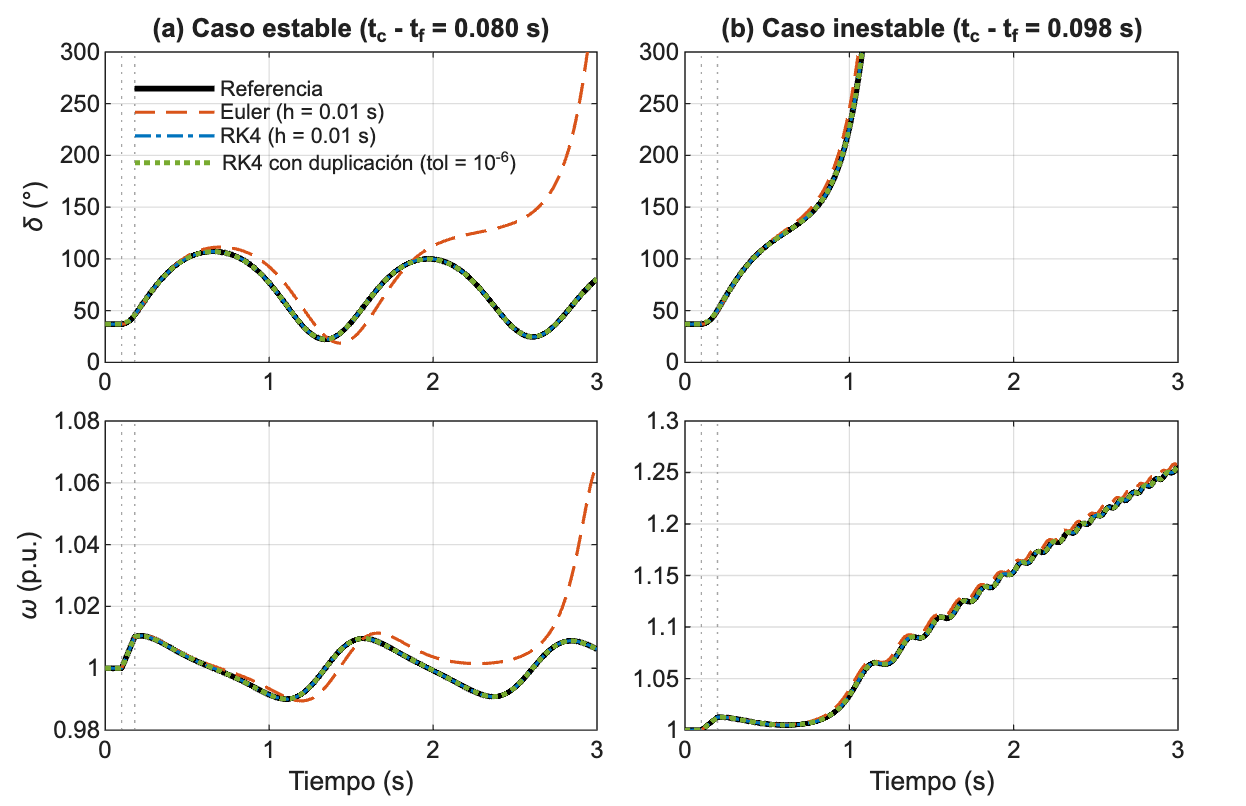

if okEu
    mact.textoEulerClasif = 'En ambos casos Euler explícito reproduce la clasificación de la referencia.';
else
    mact.textoEulerClasif = ['Con $h=\hTray$~s, Euler explícito no reproduce la clasificación de la referencia ' ...
        '(aparece una inestabilidad numérica que no existe en el sistema físico).'];
end
if okRK
    mact.textoClasifRK = 'RK4 y RK4 con duplicación de paso reproducen la clasificación de la referencia en ambos casos.';
else
    mact.textoClasifRK = 'RK4 o RK4 con duplicación de paso no reproducen la clasificación de la referencia en alguno de los casos.';
end

% --- Tabla: errores y costo en el caso base (objetivo específico ii) ---
M  = {S(1).eu, S(1).rk, S(1).sd};   Mi = {S(2).eu, S(2).rk, S(2).sd};
tT = [timeit(@() simular(p, durEst, 'euler', parE)), timeit(@() simular(p, durEst, 'rk4', parR)), ...
      timeit(@() simular(p, durEst, 'rk4sd', parS))];
nomT = {'Euler explícito', 'RK4 (paso fijo)', 'RK4 con duplicación de paso'};
cfT  = {['$h=' fG(hTray) '$ s'], ['$h=' fG(hTray) '$ s'], ['$\mathrm{tol}=' mathSci(tolTray,0) '$']};
filas = cell(4, 8);
filas(1,:) = {'Referencia', '$\mathrm{RelTol}=10^{-12}$', '---', '---', '---', '---', ...
              txtEst(esEstableRef(S(1).ref)), txtEst(esEstableRef(S(2).ref))};
for m = 1:3
    [e1, e2] = errorGlobal(M{m}, S(1).ref);
    filas(m+1,:) = {nomT{m}, cfT{m}, fSci(e1,1), fSci(e2,1), sprintf('%d', M{m}.nfev), ...
                    fFix(tT(m)*1e3,1), txtEst(esEstable(M{m}.y)), txtEst(esEstable(Mi{m}.y))};
    if m == 1, mac.errEulerTray = mathSci(e1,1); end
    if m == 2, mac.errRKTray = mathSci(e1,1);  mac.nfRKTray = sprintf('%d', M{m}.nfev); end
    if m == 3, mac.errSDTray = mathSci(e1,1);  mac.nfSDTray = sprintf('%d', M{m}.nfev); end
end
escribirTabla(fullfile(cfg.carpetaTab,'tab_tray.tex'), 'llrrrrll', ...
    {'Método','Configuración','$e_\delta$ (rad)','$e_\omega$ (p.u.)','$N_f$','$t_{\mathrm{CPU}}$ (ms)','Caso (a)','Caso (b)'}, filas);

% --- Figura 1: trayectorias delta(t) y omega(t) ---
fig = nuevaFig(17, 11);
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
tq  = linspace(0, p.T, 3001);
tit = {'(a) Caso estable', '(b) Caso inestable'};
for c = 1:2
    d  = casos(c);
    yr = evalRef(S(c).ref, tq);
    for fila = 1:2                       % 1: delta, 2: omega
        nexttile(c + 2*(fila-1)); hold on
        esc = 1;  if fila == 1, esc = 180/pi; end
        plot(tq,        yr(fila,:)*esc,          '-',  'Color', col.ref, 'LineWidth', 2.2);
        plot(S(c).eu.t, S(c).eu.y(fila,:)*esc,   '--', 'Color', col.euler);
        plot(S(c).rk.t, S(c).rk.y(fila,:)*esc,   '-.', 'Color', col.rk4);
        plot(S(c).sd.t, S(c).sd.y(fila,:)*esc,   ':',  'Color', col.sd, 'LineWidth', 1.8);
        xline(p.tf,   'Color', [.5 .5 .5], 'LineStyle', ':');
        xline(p.tf+d, 'Color', [.5 .5 .5], 'LineStyle', ':');
        grid on; box on; xlim([0 p.T]);
        if fila == 1
            ylim([0 300]);
            title(sprintf('%s (t_c - t_f = %.3f s)', tit{c}, d));
        else
            xlabel('Tiempo (s)');
        end
        if c == 1 && fila == 1, ylabel(['\delta (' char(176) ')']); end
        if c == 1 && fila == 2, ylabel('\omega (p.u.)'); end
    end
end
nexttile(1);
legend('Referencia', sprintf('Euler (h = %g s)', hTray), sprintf('RK4 (h = %g s)', hTray), ...
       sprintf('RK4 con duplicación (tol = 10^{%d})', round(log10(tolTray))), ...
       'Location', 'northwest', 'Box', 'off', 'FontSize', cfg.fs-1);
guardarFig(fig, 'fig_01_trayectorias', cfg);

## 5. Euler y RK4 de paso fijo: variación del paso h (caso estable)

refEst = S(1).ref;
errE = zeros(1,nh);  errEw = errE;  nfE = errE;  tE = errE;
errR = errE;         errRw = errE;  nfR = errE;  tR = errE;
for i = 1:nh
    par = struct('h', hList(i));
    sE = simular(p, durEst, 'euler', par);
    sR = simular(p, durEst, 'rk4',   par);
    [errE(i), errEw(i)] = errorGlobal(sE, refEst);  nfE(i) = sE.nfev;
    [errR(i), errRw(i)] = errorGlobal(sR, refEst);  nfR(i) = sR.nfev;
    tE(i) = timeit(@() simular(p, durEst, 'euler', par));
    tR(i) = timeit(@() simular(p, durEst, 'rk4',   par));
end
ordE = [NaN, log2(errE(1:end-1) ./ errE(2:end))];     % orden observado entre h y h/2
ordR = [NaN, log2(errR(1:end-1) ./ errR(2:end))];
kE = find(hList < hCritE);  kE = kE(max(1, end-2):end);   % Euler: tramo con h < h crítico
if numel(kE) < 2, kE = max(1, nh-2):nh; end
iOK = find(ordR > 3);                                  % RK4: pares (h, h/2) aún en régimen asintótico
kR  = unique([iOK-1, iOK]);  if numel(kR) < 2, kR = 1:nh; end
cE = polyfit(log(hList(kE)), log(errE(kE)), 1);
cR = polyfit(log(hList(kR)), log(errR(kR)), 1);
fprintf('Pendiente log-log (orden observado): Euler = %.2f | RK4 = %.2f\n', cE(1), cR(1));

Pendiente log-log (orden observado): Euler = 1.05 | RK4 = 3.86


mac.ordEuler = fFix(cE(1),2);  mac.ordRK = fFix(cR(1),2);
mac.errMinEuler = mathSci(min(errE),1);  mac.nfEulerMin = sprintf('%d', nfE(end));
mac.hRKmid = fG(hList(3));  mac.errRKmid = mathSci(errR(3),1);  mac.nfRKmid = sprintf('%d', nfR(3));
if any(ordR(2:end) < 2)      % el error deja de decrecer: se llegó al piso de la referencia
    mact.textoPisoRK = ['En los pasos más finos el error de RK4 deja de decrecer (mínimo $' mathSci(min(errR),1) ...
        '$~rad): se alcanzó la precisión de la solución de referencia y $\hat{p}$ deja de ser informativo.'];
else
    mact.textoPisoRK = '';
end

filas = cell(nh, 9);
for i = 1:nh
    filas(i,:) = {fG(hList(i)), sprintf('%d',nfE(i)), fSci(errE(i),2), fSci(errEw(i),2), fFix(ordE(i),2), ...
                  sprintf('%d',nfR(i)), fSci(errR(i),2), fSci(errRw(i),2), fFix(ordR(i),2)};
end
escribirTabla(fullfile(cfg.carpetaTab,'tab_convergencia.tex'), 'rrrrrrrrr', ...
    {'$h$ (s)','$N_f$','$e_\delta$','$e_\omega$','$\hat{p}$','$N_f$','$e_\delta$','$e_\omega$','$\hat{p}$'}, filas, ...
    '& \multicolumn{4}{c}{Euler explícito} & \multicolumn{4}{c}{RK4 (paso fijo)} \\ \cmidrule(lr){2-5}\cmidrule(lr){6-9}');

## 6. RK4 con duplicación de paso: variación de tol, y comparación costo-precisión

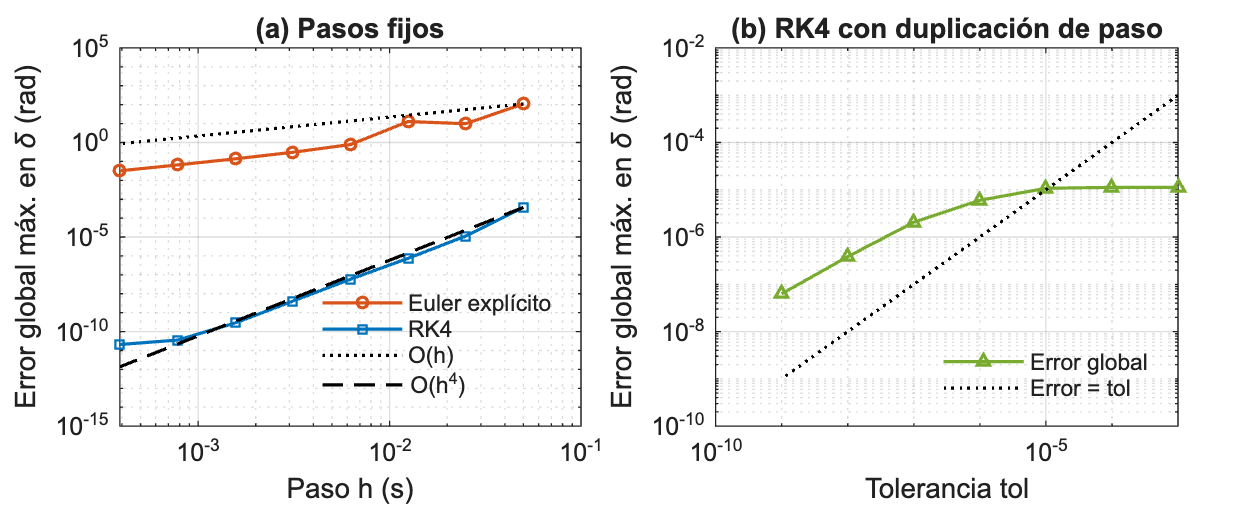

errS = zeros(1,nt);  errSw = errS;  nfS = errS;  naS = errS;  nrS = errS;  hmS = errS;  hMS = errS;  tS = errS;
for i = 1:nt
    par = struct('tol', tolList(i), 'opt', optSD);
    s = simular(p, durEst, 'rk4sd', par);
    [errS(i), errSw(i)] = errorGlobal(s, refEst);
    nfS(i) = s.nfev;  naS(i) = s.nacc;  nrS(i) = s.nrej;
    hl = s.hacc(~s.clip);                       % se excluyen los pasos recortados en las fronteras
    hmS(i) = min(hl);  hMS(i) = max(hl);
    tS(i) = timeit(@() simular(p, durEst, 'rk4sd', par));
end
no = numel(rtList);
errO = zeros(1,no);  nfO = errO;  tO = errO;
for i = 1:no
    rt = rtList(i);
    s = simularRef(p, durEst, rt, 1e-2*rt);
    errO(i) = errorNodos(s, refEst);  nfO(i) = s.nfev;
    tO(i) = timeit(@() simularRef(p, durEst, rt, 1e-2*rt));
end

% --- Tabla: RK4 con duplicación de paso ---
filas = cell(nt, 9);
for i = 1:nt
    filas(i,:) = {fSci(tolList(i),0), fSci(errS(i),2), fSci(errSw(i),2), sprintf('%d',nfS(i)), sprintf('%d',naS(i)), ...
                  sprintf('%d',nrS(i)), fFix(hmS(i)*1e3,2), fFix(hMS(i)*1e3,1), fFix(tS(i)*1e3,1)};
end
escribirTabla(fullfile(cfg.carpetaTab,'tab_adaptativo.tex'), 'rrrrrrrrr', ...
    {'tol','$e_\delta$','$e_\omega$','$N_f$','Aceptados','Rechazados','$h_{\min}$ (ms)','$h_{\max}$ (ms)','$t_{\mathrm{CPU}}$ (ms)'}, filas);

% --- Tabla: costo para alcanzar un error objetivo ---
objetivos = [1e-3, 1e-6];
nom  = {'Euler explícito','RK4 (paso fijo)','RK4 con duplicación de paso','ode45 (referencia externa)'};
DAT  = {errE, nfE, tE; errR, nfR, tR; errS, nfS, tS; errO, nfO, tO};
filas = cell(4, 1 + 2*numel(objetivos));
NFO = NaN(4, numel(objetivos));
for m = 1:4
    filas{m,1} = nom{m};
    for q = 1:numel(objetivos)
        idx = find(DAT{m,1} <= objetivos(q));
        if isempty(idx)
            filas{m,2*q} = '---';  filas{m,2*q+1} = '---';
        else
            [~, j] = min(DAT{m,2}(idx));  j = idx(j);
            NFO(m,q) = DAT{m,2}(j);
            filas{m,2*q}   = sprintf('%d', DAT{m,2}(j));
            filas{m,2*q+1} = fFix(DAT{m,3}(j)*1e3, 1);
        end
    end
end
escribirTabla(fullfile(cfg.carpetaTab,'tab_eficiencia.tex'), '>{\raggedright\arraybackslash}p{2.6cm}rrrr', ...
    {'Método','$N_f$','$t_{\mathrm{CPU}}$ (ms)','$N_f$','$t_{\mathrm{CPU}}$ (ms)'}, filas, ...
    ['& \multicolumn{2}{c}{$e_\delta \le ' mathSci(objetivos(1),0) '$ rad} & \multicolumn{2}{c}{$e_\delta \le ' ...
     mathSci(objetivos(2),0) '$ rad} \\ \cmidrule(lr){2-3}\cmidrule(lr){4-5}']);
mac.errObjA = mathSci(objetivos(1),0);  mac.errObjB = mathSci(objetivos(2),0);
mac.nfARK = fFix(NFO(2,1),0);  mac.nfASD = fFix(NFO(3,1),0);     % N_f para alcanzar el error objetivo A
mac.nfBRK = fFix(NFO(2,2),0);  mac.nfBSD = fFix(NFO(3,2),0);     % ... y el objetivo B

% --- Figura 2: convergencia ---
fig = nuevaFig(17, 7);
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; hold on
plot(hList, errE, 'o-', 'Color', col.euler, 'MarkerSize', 4);
plot(hList, errR, 's-', 'Color', col.rk4,   'MarkerSize', 4);
plot(hList, errE(1)*(hList/hList(1)),    'k:');
plot(hList, errR(1)*(hList/hList(1)).^4, 'k--');
set(gca, 'XScale', 'log', 'YScale', 'log'); grid on; box on
xlabel('Paso h (s)'); ylabel('Error global máx. en \delta (rad)'); title('(a) Pasos fijos');
legend('Euler explícito', 'RK4', 'O(h)', 'O(h^4)', 'Location', 'southeast', 'Box', 'off');
nexttile; hold on
plot(tolList, errS, '^-', 'Color', col.sd, 'MarkerSize', 4);
plot(tolList, tolList, 'k:');
set(gca, 'XScale', 'log', 'YScale', 'log'); grid on; box on
xlabel('Tolerancia tol'); ylabel('Error global máx. en \delta (rad)'); title('(b) RK4 con duplicación de paso');
legend('Error global', 'Error = tol', 'Location', 'southeast', 'Box', 'off');
guardarFig(fig, 'fig_02_convergencia', cfg);

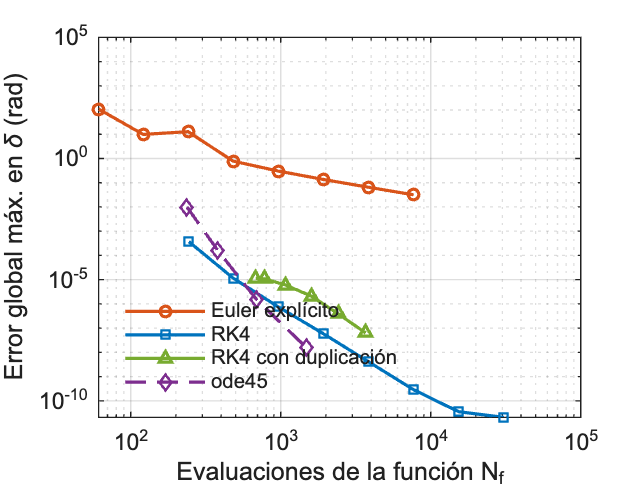


% --- Figura 4: curva de eficiencia (error vs. evaluaciones de f) ---
fig = nuevaFig(8.5, 6.5);  hold on
plot(nfE, errE, 'o-',  'Color', col.euler, 'MarkerSize', 4);
plot(nfR, errR, 's-',  'Color', col.rk4,   'MarkerSize', 4);
plot(nfS, errS, '^-',  'Color', col.sd,    'MarkerSize', 4);
plot(nfO, errO, 'd--', 'Color', col.ode,   'MarkerSize', 4);
set(gca, 'XScale', 'log', 'YScale', 'log'); grid on; box on
xlabel('Evaluaciones de la función N_f'); ylabel('Error global máx. en \delta (rad)');
legend('Euler explícito', 'RK4', 'RK4 con duplicación', 'ode45', 'Location', 'southwest', 'Box', 'off');
guardarFig(fig, 'fig_04_eficiencia', cfg);

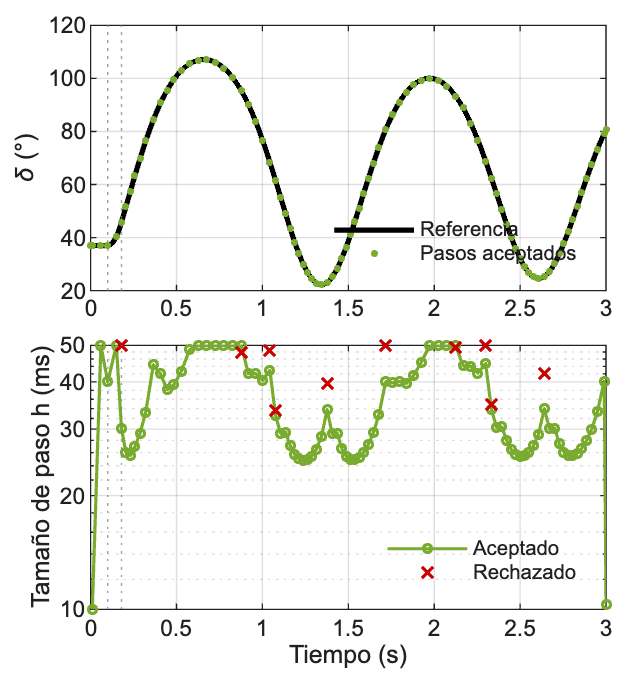


% --- Figura 3: historial del paso adaptativo (caso estable, tol = tolTray) ---
sd = S(1).sd;  yr = evalRef(S(1).ref, tq);
fig = nuevaFig(8.5, 9);
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; hold on
plot(tq, yr(1,:)*180/pi, '-', 'Color', col.ref, 'LineWidth', 2);
plot(sd.t, sd.y(1,:)*180/pi, '.', 'Color', col.sd, 'MarkerSize', 8);
xline(p.tf, 'Color', [.5 .5 .5], 'LineStyle', ':');  xline(p.tf+durEst, 'Color', [.5 .5 .5], 'LineStyle', ':');
grid on; box on; xlim([0 p.T]); ylabel(['\delta (' char(176) ')']);
legend('Referencia', 'Pasos aceptados', 'Location', 'southeast', 'Box', 'off');
nexttile; hold on
plot(sd.tacc, sd.hacc*1e3, '-o', 'Color', col.sd, 'MarkerSize', 3);
if ~isempty(sd.trej), plot(sd.trej, sd.hrej*1e3, 'x', 'Color', [0.8 0 0], 'MarkerSize', 6); end
xline(p.tf, 'Color', [.5 .5 .5], 'LineStyle', ':');  xline(p.tf+durEst, 'Color', [.5 .5 .5], 'LineStyle', ':');
set(gca, 'YScale', 'log'); grid on; box on; xlim([0 p.T]);
xlabel('Tiempo (s)'); ylabel('Tamaño de paso h (ms)');
if ~isempty(sd.trej), legend('Aceptado', 'Rechazado', 'Location', 'southeast', 'Box', 'off'); end
guardarFig(fig, 'fig_03_paso_adaptativo', cfg);

mac.nAceptSD = sprintf('%d', sd.nacc);  mac.nRechSD = sprintf('%d', sd.nrej);
mac.nIntSD = sprintf('%d', sd.nacc + sd.nrej);

## 7. CCT por método: búsqueda incremental + bisección (D del caso base y D = 0)

cctE = zeros(1,nh);  nsE = cctE;  cctR = cctE;  nsR = cctE;
for i = 1:nh
    par = struct('h', hList(i));
    [cctE(i), nsE(i)] = buscarCCT(@(d) estSim(p, d, 'euler', par), cfg);
    [cctR(i), nsR(i)] = buscarCCT(@(d) estSim(p, d, 'rk4',   par), cfg);
end
ntc = numel(tolCCTl);  cctS = zeros(1,ntc);  nsS = cctS;
for i = 1:ntc
    par = struct('tol', tolCCTl(i), 'opt', optSD);
    [cctS(i), nsS(i)] = buscarCCT(@(d) estSim(p, d, 'rk4sd', par), cfg);
end
nsel = numel(selH);  cctE0 = zeros(1,nsel);  cctR0 = cctE0;  cctS0 = zeros(1,ntc);
for i = 1:nsel
    par = struct('h', hList(selH(i)));
    cctE0(i) = buscarCCT(@(d) estSim(p0, d, 'euler', par), cfg);
    cctR0(i) = buscarCCT(@(d) estSim(p0, d, 'rk4',   par), cfg);
end
for i = 1:ntc
    par = struct('tol', tolCCTl(i), 'opt', optSD);
    cctS0(i) = buscarCCT(@(d) estSim(p0, d, 'rk4sd', par), cfg);
end
fprintf('CCT Euler : %s\n', sprintf('%.4f ', cctE));

CCT Euler : 0.0000 0.0453 0.0737 0.0871 0.0881 0.0885 0.0887 0.0889 


fprintf('CCT RK4   : %s\n', sprintf('%.4f ', cctR));

CCT RK4   : 0.0890 0.0890 0.0890 0.0890 0.0890 0.0890 0.0890 0.0890 


fprintf('CCT RK4-SD: %s\n', sprintf('%.4f ', cctS));

CCT RK4-SD: 0.0890 0.0890 0.0890 0.0890 


fprintf('D=0  Euler: %s | RK4: %s | SD: %s | analitico %.4f\n', sprintf('%.4f ', cctE0), sprintf('%.4f ', cctR0), sprintf('%.4f ', cctS0), cctAn);

D=0  Euler: 0.0328 0.0738 0.0833 0.0852  | RK4: 0.0853 0.0853 0.0853 0.0853  | SD: 0.0853 0.0853 0.0853 0.0853  | analitico 0.0853


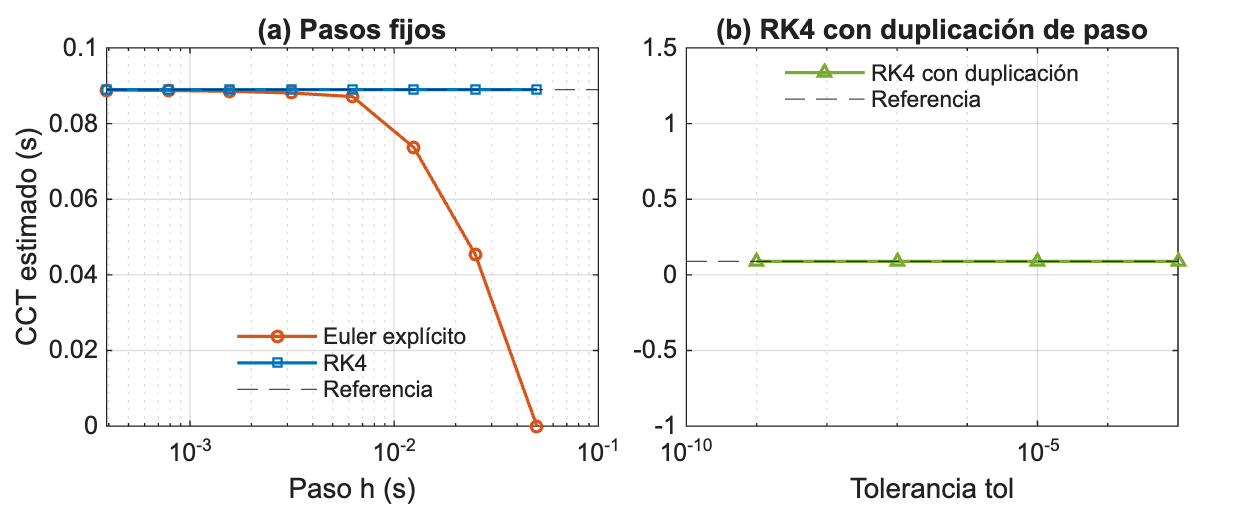


% --- Tabla: CCT estimado por cada integrador ---
filas = cell(0, 6);
filas(end+1,:) = {'Referencia (\texttt{ode45})', '$\mathrm{RelTol}=10^{-12}$', fFix(cctRef,4), '---', fFix(cctRef0,4), fFix(abs(cctRef0-cctAn)*1e3,3)};
filas(end+1,:) = {'Áreas iguales', '---', '---', '---', fFix(cctAn,4), '---'};
for i = 1:nsel
    nm = '';  if i == 1, nm = 'Euler explícito'; end
    filas(end+1,:) = {nm, ['$h=' fG(hList(selH(i))) '$'], fFix(cctE(selH(i)),4), fFix(abs(cctE(selH(i))-cctRef)*1e3,2), ...
                      fFix(cctE0(i),4), fFix(abs(cctE0(i)-cctAn)*1e3,2)};
end
for i = 1:nsel
    nm = '';  if i == 1, nm = 'RK4 (paso fijo)'; end
    filas(end+1,:) = {nm, ['$h=' fG(hList(selH(i))) '$'], fFix(cctR(selH(i)),4), fFix(abs(cctR(selH(i))-cctRef)*1e3,3), ...
                      fFix(cctR0(i),4), fFix(abs(cctR0(i)-cctAn)*1e3,3)};
end
for i = 1:ntc
    nm = '';  if i == 1, nm = 'RK4 con duplicación'; end
    filas(end+1,:) = {nm, ['$\mathrm{tol}=' mathSci(tolCCTl(i),0) '$'], fFix(cctS(i),4), fFix(abs(cctS(i)-cctRef)*1e3,3), ...
                      fFix(cctS0(i),4), fFix(abs(cctS0(i)-cctAn)*1e3,3)};
end
escribirTabla(fullfile(cfg.carpetaTab,'tab_cct.tex'), 'llrrrr', ...
    {'Método','Parámetro','CCT (s)','$|\Delta|$ (ms)','CCT (s)','$|\Delta|$ (ms)'}, filas, ...
    '& & \multicolumn{2}{c}{$D=\Dbase$ (frente a la referencia)} & \multicolumn{2}{c}{$D=0$ (frente al analítico)} \\ \cmidrule(lr){3-4}\cmidrule(lr){5-6}');

mac.errCCTEulerGrueso = fFix(abs(cctE(1)-cctRef)*1e3,1);
mac.errCCTEulerFino   = fFix(abs(cctE(end)-cctRef)*1e3,2);
mac.errCCTRKmax       = fFix(max(abs(cctR-cctRef))*1e3,3);
mac.errCCTSDmax       = fFix(max(abs(cctS-cctRef))*1e3,3);
mac.errCCTcerRK      = fFix(max(abs(cctR0-cctAn))*1e3,3);
mac.errCCTcerSD      = fFix(max(abs(cctS0-cctAn))*1e3,3);
mac.errCCTcerEulerFino  = fFix(abs(cctE0(end)-cctAn)*1e3,2);
mac.hGrueso = fG(hList(1));  mac.hFino = fG(hList(end));
mac.cctEulerGrueso = fFix(cctE(1),4);  mac.cctEulerFino = fFix(cctE(end),4);
mac.nSimMax = sprintf('%d', max([nsE nsR nsS]));

% --- Figura 5: CCT frente a h y a tol ---
fig = nuevaFig(17, 7);
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; hold on
plot(hList, cctE, 'o-', 'Color', col.euler, 'MarkerSize', 4);
plot(hList, cctR, 's-', 'Color', col.rk4,   'MarkerSize', 4);
yline(cctRef, 'Color', 'k', 'LineStyle', '--');
set(gca, 'XScale', 'log'); grid on; box on
xlabel('Paso h (s)'); ylabel('CCT estimado (s)'); title('(a) Pasos fijos');
legend('Euler explícito', 'RK4', 'Referencia', 'Location', 'best', 'Box', 'off');
nexttile; hold on
plot(tolCCTl, cctS, '^-', 'Color', col.sd, 'MarkerSize', 4);
yline(cctRef, 'Color', 'k', 'LineStyle', '--');
set(gca, 'XScale', 'log'); grid on; box on
xlabel('Tolerancia tol'); title('(b) RK4 con duplicación de paso');
legend('RK4 con duplicación', 'Referencia', 'Location', 'best', 'Box', 'off');
guardarFig(fig, 'fig_05_cct_metodos', cfg);

## 8. Sensibilidad a la inercia H y a la potencia mecánica Pm

Para cada (H, Pm): CCT de referencia y error de cada integrador en el caso estable de 0.9·CCT, con una configuración fija por método.

nH = numel(Hs);  nP = numel(Pms);
cctHP = zeros(nH, nP);  eHP = zeros(nH, nP, 3);  d0HP = zeros(nH, nP);  hcHP = zeros(nH, nP);
for i = 1:nH
    for j = 1:nP
        pp = p;  pp.H = Hs(i);  pp = cambiarPm(pp, Pms(j));
        cctHP(i,j) = buscarCCT(@(d) estRef(pp, d), cfg);
        dur  = 0.9*cctHP(i,j);  sref = simularRef(pp, dur);
        eHP(i,j,1) = errorGlobal(simular(pp, dur, 'euler', struct('h', hSensE)), sref);
        eHP(i,j,2) = errorGlobal(simular(pp, dur, 'rk4',   struct('h', hSensR)), sref);
        eHP(i,j,3) = errorGlobal(simular(pp, dur, 'rk4sd', struct('tol', tolSens, 'opt', optSD)), sref);
        d0HP(i,j)  = pp.delta0*180/pi;
        hcHP(i,j)  = pp.D/(pp.wb*pp.Pmax(3)*cos(pp.dsPost));
    end
end
filas = cell(nH*nP, 7);  k = 0;
for i = 1:nH
    for j = 1:nP
        k = k + 1;
        filas(k,:) = {fFix(Hs(i),1), fFix(Pms(j),2), fFix(d0HP(i,j),1), fFix(cctHP(i,j),4), ...
                      fSci(eHP(i,j,1),1), fSci(eHP(i,j,2),1), fSci(eHP(i,j,3),1)};
    end
end
escribirTabla(fullfile(cfg.carpetaTab,'tab_sensibilidad.tex'), 'rrrrrrr', ...
    {'$H$ (s)','$P_m$ (p.u.)','$\delta_0$ (grados)','CCT (s)','Euler','RK4','RK4 con dup.'}, filas, ...
    '& & & & \multicolumn{3}{c}{$e_\delta$ (rad)} \\ \cmidrule(lr){5-7}');
[~, iH0] = min(abs(Hs - p.H));  [~, jP0] = min(abs(Pms - p.Pm));
fprintf('CCT(H=%.1f, Pm=%.2f) = %.6f s (referencia base %.6f s)\n', Hs(iH0), Pms(jP0), cctHP(iH0,jP0), cctRef);

CCT(H=3.5, Pm=0.90) = 0.088965 s (referencia base 0.088965 s)


disp(cctHP);  disp(squeeze(eHP(:,:,1)));  disp(squeeze(eHP(:,:,2)));  disp(squeeze(eHP(:,:,3)));

         0.153177185058594        0.0757455444335938        0.0253097534179688
         0.180506286621094        0.0889645385742187        0.0289572143554687
         0.214963684082031         0.105630187988281        0.0335476684570313

         0.292267083080095         0.238076857503421         0.318460369185814
         0.261954682534151         0.136457422033992         0.224328195543855
         0.116923645411548         0.123489957419785         0.186495149189338

      9.50921782605363e-06      1.46765171105123e-06      3.56002685419909e-06
      3.80620001472209e-06      7.49042357695018e-07      1.93070549037166e-06
      1.93884518284726e-06      3.01666051694127e-07      9.88480229668909e-07

      8.85409084550037e-06      7.38389775301052e-06      7.09058100345494e-06
      7.60798493237846e-06      5.99370173148817e-06      2.74594010307716e-06
      6.68524084157518e-06      3.87655959732669e-06      3.16796387700435e-06



mac.Hlo = fFix(Hs(1),1);   mac.Hhi = fFix(Hs(end),1);   mac.cctHlo = fFix(cctHP(1,jP0),4);   mac.cctHhi = fFix(cctHP(end,jP0),4);
mac.Plo = fFix(Pms(1),1);  mac.Phi = fFix(Pms(end),1);  mac.cctPlo = fFix(cctHP(iH0,1),4);   mac.cctPhi = fFix(cctHP(iH0,end),4);
mac.eEmin = mathSci(min(min(eHP(:,:,1))),1);  mac.eEmax = mathSci(max(max(eHP(:,:,1))),1);
mac.eRmin = mathSci(min(min(eHP(:,:,2))),1);  mac.eRmax = mathSci(max(max(eHP(:,:,2))),1);
mac.eSmin = mathSci(min(min(eHP(:,:,3))),1);  mac.eSmax = mathSci(max(max(eHP(:,:,3))),1);
mac.hSensE = fG(hSensE);  mac.hSensR = fG(hSensR);  mac.tolSens = mathSci(tolSens,0);
mac.hCritMinSens = fFix(min(min(hcHP)),4);

## 9. Exportación de macros LaTeX

escribirMacros(mac, mact, 'macros_resultados.tex');
fprintf('\nListo. Se generaron %s, %s y macros_resultados.tex\n', cfg.carpetaFig, cfg.carpetaTab);


Listo. Se generaron figuras, tablas y macros_resultados.tex


## Funciones locales

NOTA: si la plantilla del curso ya incluye funciones locales (p. ej. para Euler o RK4), NO las modifiques: pégalas tal cual en esta sección, borra la versión equivalente de aquí y adapta únicamente las llamadas del script.

function p = calcularSistema(p)
% Flujo de potencia previo (SMIB, red sin pérdidas) y datos derivados.
Xpre  = p.Xd + p.XT + p.XL/2;            % ambas líneas en servicio
Xpost = p.Xd + p.XT + p.XL;              % una línea fuera de servicio tras el despeje
I  = conj((p.P0 + 1i*p.Q0) / p.Vt);      % corriente inyectada
E  = p.Vt + 1i*p.Xd*I;                   % FEM interna transitoria
Vi = p.Vt - 1i*(p.XT + p.XL/2)*I;        % tensión de la barra infinita
p.E = abs(E);  p.Vinf = abs(Vi);
p.delta0 = angle(E) - angle(Vi);         % ángulo inicial del rotor [rad]
p.Pm   = p.P0;                           % Pm constante (supuesto 2)
p.Pmax = [p.E*p.Vinf/Xpre, 0, p.E*p.Vinf/Xpost];   % [pre-falla, falla, post-despeje]
p.dsPost = asin(p.Pm/p.Pmax(3));         % equilibrio estable post-despeje
p.duPost = pi - p.dsPost;                % equilibrio inestable post-despeje
end

function p = cambiarPm(p, Pm)
% Cambia la potencia mecánica manteniendo E', V_inf y la red del caso base.
p.Pm = Pm;
p.delta0 = asin(Pm/p.Pmax(1));
p.dsPost = asin(Pm/p.Pmax(3));
p.duPost = pi - p.dsPost;
end

function s = txtEst(ok)
if ok, s = 'Estable'; else, s = 'Inestable'; end
end

function f = crearRHS(p, Pmax)
% Ecuaciones de oscilación: y = [delta; omega] con omega en p.u.
wb = p.wb;  H = p.H;  D = p.D;  Pm = p.Pm;
f = @(t, y) [wb*(y(2) - 1); (Pm - Pmax*sin(y(1)) - D*(y(2) - 1))/(2*H)];
end

function yn = rk4Paso(f, t, y, h, k1)
% Un paso de RK4 clásico (Ecs. 28-32 del documento). Si se entrega k1 = f(t,y),
% no se vuelve a evaluar (la duplicación de paso lo comparte entre sus pasos).
if nargin < 5, k1 = f(t, y); end
k2 = f(t + h/2, y + h/2*k1);
k3 = f(t + h/2, y + h/2*k2);
k4 = f(t + h,   y + h*k3);
yn = y + h/6*(k1 + 2*k2 + 2*k3 + k4);
end

function [t, Y, nfev] = eulerFijo(f, t0, t1, y0, h)
% Euler explícito (Ec. 13). El paso se ajusta para llegar exactamente a t1.
N  = max(1, ceil((t1 - t0)/h - 1e-9));
hh = (t1 - t0)/N;
t  = t0 + (0:N)*hh;  t(end) = t1;
Y  = zeros(numel(y0), N+1);  Y(:,1) = y0(:);
for n = 1:N
    Y(:,n+1) = Y(:,n) + hh*f(t(n), Y(:,n));
end
nfev = N;
end

function [t, Y, nfev] = rk4Fijo(f, t0, t1, y0, h)
% RK4 de paso fijo. El paso se ajusta para llegar exactamente a t1.
N  = max(1, ceil((t1 - t0)/h - 1e-9));
hh = (t1 - t0)/N;
t  = t0 + (0:N)*hh;  t(end) = t1;
Y  = zeros(numel(y0), N+1);  Y(:,1) = y0(:);
for n = 1:N
    Y(:,n+1) = rk4Paso(f, t(n), Y(:,n), hh);
end
nfev = 4*N;
end

function [t, Y, nfev, info] = rk4SD(f, t0, t1, y0, hprop, tol, opt)
% RK4 con duplicación de paso (Ecs. 29-33): un paso h frente a dos de h/2.
% Cada intento cuesta 11 evaluaciones de f (k1 compartido: 1 + 3 + 3 + 4), aceptado o rechazado.
tn = t0;  yn = y0(:);
t = tn;   Y = yn;
nfev = 0;  nacc = 0;  nrej = 0;
hacc = [];  clip = logical([]);  trej = [];  hrej = [];
hprop = min(max(hprop, opt.hmin), opt.hmax);
while tn < t1
    h = hprop;  fin = false;
    if tn + h >= t1                           % no cruzar la frontera del régimen
        h = t1 - tn;  fin = true;
    end
    k1 = f(tn, yn);                           % evaluación inicial común (1)
    y1 = rk4Paso(f, tn,       yn, h,   k1);   % un paso completo (3 más)
    ym = rk4Paso(f, tn,       yn, h/2, k1);   % primer medio paso (3 más)
    y2 = rk4Paso(f, tn + h/2, ym, h/2);       % segundo medio paso (4)
    nfev = nfev + 11;
    err = norm(y1 - y2, Inf);                 % Ec. (32)
    if ~isfinite(err)                         % divergencia numérica: se aborta el tramo
        t(end+1) = t1;  Y(:,end+1) = NaN(size(yn));
        break
    end
    fac = opt.alpha * (tol / max(err, 1e-300))^0.2;    % Ec. (33)
    fac = min(opt.fmax, max(opt.fmin, fac));
    if err <= tol || h <= opt.hmin            % paso aceptado (se usa y2)
        tn = tn + h;  if fin, tn = t1; end
        yn = y2;
        t(end+1) = tn;  Y(:,end+1) = yn;
        hacc(end+1) = h;  clip(end+1) = fin;  nacc = nacc + 1;
        if fin
            hprop = min(opt.hmax, max(hprop, fac*h));
        else
            hprop = min(opt.hmax, fac*h);
        end
    else                                      % paso rechazado: se repite con h menor
        nrej = nrej + 1;  trej(end+1) = tn;  hrej(end+1) = h;
        hprop = max(opt.hmin, fac*h);
    end
end
info = struct('h', hacc, 't', t(2:end), 'clip', clip, 'trej', trej, 'hrej', hrej, ...
              'nacc', nacc, 'nrej', nrej, 'hsig', hprop);
end

function sol = simular(p, dur, metodo, par)
% Integra los tres regímenes (pre-falla, falla, post-despeje) con el método
% indicado: 'euler', 'rk4' o 'rk4sd'. La falla dura 'dur' segundos desde p.tf.
tc = p.tf + dur;
ab = [0 p.tf; p.tf tc; tc p.T];
y  = [p.delta0; 1.0];
tt = 0;  yy = y;
nfev = 0;  nacc = 0;  nrej = 0;
hacc = [];  tacc = [];  clip = logical([]);  trej = [];  hrej = [];
hprop = 0.01;
for k = 1:3
    a = ab(k,1);  b = ab(k,2);
    if b <= a, continue; end
    f = crearRHS(p, p.Pmax(k));
    switch metodo
        case 'euler'
            [t, Y, n] = eulerFijo(f, a, b, y, par.h);
        case 'rk4'
            [t, Y, n] = rk4Fijo(f, a, b, y, par.h);
        case 'rk4sd'
            [t, Y, n, info] = rk4SD(f, a, b, y, hprop, par.tol, par.opt);
            hprop = info.hsig;
            nacc = nacc + info.nacc;  nrej = nrej + info.nrej;
            hacc = [hacc, info.h];  tacc = [tacc, info.t];  clip = [clip, info.clip];
            trej = [trej, info.trej];  hrej = [hrej, info.hrej];
        otherwise
            error('Método no reconocido: %s', metodo);
    end
    tt = [tt, t(2:end)];  yy = [yy, Y(:,2:end)];
    y  = Y(:,end);  nfev = nfev + n;
end
sol.t = tt;  sol.y = yy;  sol.nfev = nfev;  sol.nacc = nacc;  sol.nrej = nrej;
sol.hacc = hacc;  sol.tacc = tacc;  sol.clip = clip;  sol.trej = trej;  sol.hrej = hrej;
end

function s = simularRef(p, dur, rt, at)
% Solución de referencia (o benchmark ode45 si se cambian las tolerancias).
if nargin < 3, rt = 1e-12;  at = 1e-14; end
tc = p.tf + dur;
ab = [0 p.tf; p.tf tc; tc p.T];
opts = odeset('RelTol', rt, 'AbsTol', at);
y = [p.delta0; 1.0];
s.seg = {};  s.ab = zeros(0,2);  s.nfev = 0;
for k = 1:3
    a = ab(k,1);  b = ab(k,2);
    if b <= a, continue; end
    f  = crearRHS(p, p.Pmax(k));
    sk = ode45(f, [a b], y, opts);
    s.seg{end+1} = sk;  s.ab(end+1,:) = [a b];
    s.nfev = s.nfev + sk.stats.nfevals;
    y = sk.y(:,end);
end
end

function yq = evalRef(s, tq)
% Evalúa la solución de referencia en los instantes tq (salida densa de ode45).
yq = zeros(2, numel(tq));
for k = 1:size(s.ab,1)
    a = s.ab(k,1);  b = s.ab(k,2);
    idx = tq >= a - 1e-12 & tq <= b + 1e-12;
    if any(idx)
        yq(:,idx) = deval(s.seg{k}, min(max(tq(idx), a), b));
    end
end
end

function [t, y] = nodosRef(s)
% Instantes y estados en los que ode45 dio sus pasos.
t = [];  y = [];
for k = 1:numel(s.seg)
    t = [t, s.seg{k}.x];  y = [y, s.seg{k}.y];
end
end

function [e, eW] = errorGlobal(sol, sref)
% Error global máximo en delta [rad] y en omega [p.u.] en los nodos de la solución numérica.
yr = evalRef(sref, sol.t);
e  = max(abs(sol.y(1,:) - yr(1,:)));
eW = max(abs(sol.y(2,:) - yr(2,:)));
end

function [e, eW] = errorNodos(s, sref)
[t, y] = nodosRef(s);
yr = evalRef(sref, t);
e  = max(abs(y(1,:) - yr(1,:)));
eW = max(abs(y(2,:) - yr(2,:)));
end

function ok = esEstable(y)
% Criterio de estabilidad: el ángulo no supera 180° en [0, T] y no hay NaN/Inf.
ok = all(isfinite(y(:))) && max(y(1,:)) < pi;
end

function ok = estSim(p, dur, metodo, par)
s  = simular(p, dur, metodo, par);
ok = esEstable(s.y);
end

function ok = esEstableRef(s)
ok = max(cellfun(@(sk) max(sk.y(1,:)), s.seg)) < pi;
end

function [cct, nsim] = buscarCCT(estFun, cfg)
% Búsqueda incremental (paso cfg.pasoCCT) para acotar el CCT y bisección
% (tolerancia cfg.tolCCT) para refinarlo. estFun(d) = true si es estable.
nsim = 0;  lo = 0;  hi = NaN;  d = cfg.pasoCCT;
while d <= cfg.durMax + 1e-12
    nsim = nsim + 1;
    if estFun(d)
        lo = d;  d = d + cfg.pasoCCT;
    else
        hi = d;  break
    end
end
if isnan(hi), cct = NaN; return; end
while hi - lo > cfg.tolCCT
    mid = 0.5*(lo + hi);  nsim = nsim + 1;
    if estFun(mid), lo = mid; else, hi = mid; end
end
cct = 0.5*(lo + hi);
end

function [cct, dcr] = cctAnalitico(p)
% Criterio de áreas iguales con D = 0 y Pe = 0 durante la falla.
Pm = p.Pm;  P2 = p.Pmax(3);  d0 = p.delta0;
dmax = pi - asin(Pm/P2);
dcr  = acos((Pm*(dmax - d0) + P2*cos(dmax)) / P2);
cct  = sqrt(4*p.H*(dcr - d0) / (p.wb*Pm));
end

function s = fFix(x, nd)
if ~isfinite(x), s = '---'; else, s = sprintf('%.*f', nd, x); end
end

function s = fG(x)
s = sprintf('%g', x);
end

function s = mathSci(x, nd)
% Notación científica en modo matemático (sin signos $).
if ~isfinite(x), s = '---'; return; end
if x == 0, s = '0'; return; end
e  = floor(log10(abs(x)));  m = x / 10^e;
ms = sprintf('%.*f', nd, m);
if abs(str2double(ms)) >= 10
    e = e + 1;  m = x / 10^e;  ms = sprintf('%.*f', nd, m);
end
if nd == 0 && strcmp(ms, '1')
    s = sprintf('10^{%d}', e);
else
    s = sprintf('%s\\times10^{%d}', ms, e);
end
end

function s = fSci(x, nd)
if ~isfinite(x), s = '---'; else, s = ['$' mathSci(x, nd) '$']; end
end

function escribirTabla(archivo, colspec, encab, filas, supHdr)
% Escribe un tabular con estilo APA (booktabs, sin líneas verticales).
fid = fopen(archivo, 'w', 'n', 'UTF-8');
fprintf(fid, '%% Generado automáticamente por avance3_estabilidad_transitoria\n');
fprintf(fid, '\\begin{tabular}{%s}\n\\toprule\n', colspec);
if nargin > 4 && ~isempty(supHdr), fprintf(fid, '%s\n', supHdr); end
fprintf(fid, '%s \\\\\n\\midrule\n', strjoin(encab, ' & '));
for i = 1:size(filas,1)
    fprintf(fid, '%s \\\\\n', strjoin(filas(i,:), ' & '));
end
fprintf(fid, '\\bottomrule\n\\end{tabular}\n');
fclose(fid);
end

function escribirMacros(mac, mact, archivo)
% Una macro por valor clave (cifras) o por frase condicionada (texto).
fid = fopen(archivo, 'w', 'n', 'UTF-8');
fprintf(fid, '%% Generado automáticamente por avance3_estabilidad_transitoria\n');
nombres = fieldnames(mac);
for i = 1:numel(nombres)
    fprintf(fid, '\\providecommand{\\%s}{}\\renewcommand{\\%s}{\\ensuremath{%s}}\n', ...
        nombres{i}, nombres{i}, mac.(nombres{i}));
end
nombres = fieldnames(mact);
for i = 1:numel(nombres)
    fprintf(fid, '\\providecommand{\\%s}{}\\renewcommand{\\%s}{%s}\n', ...
        nombres{i}, nombres{i}, mact.(nombres{i}));
end
fclose(fid);
end

function fig = nuevaFig(wcm, hcm)
fig = figure('Color', 'w', 'Units', 'centimeters', 'Position', [3 3 wcm hcm]);
end

function guardarFig(fig, nombre, cfg)
% Exporta en PDF (vectorial) y PNG (300 dpi).
base = fullfile(cfg.carpetaFig, nombre);
try
    exportgraphics(fig, [base '.pdf'], 'ContentType', 'vector');
    exportgraphics(fig, [base '.png'], 'Resolution', 300);
catch
    print(fig, [base '.png'], '-dpng', '-r300');
    print(fig, [base '.pdf'], '-dpdf');
end
end